# 802.11ad Packet Error Rate Single Carrier PHY Simulation with TGay Channel

This example shows how to measure the packet error rate of an IEEE® 802.11ad™ DMG single carrier (SC) PHY link using an end-to-end simulation. 

## Introduction

In this example an end-to-end simulation is used to determine the packet error rate for an 802.11ad SC [ [1](about:blank<#13>) ] link with a TGay millimeter-wave channel [ [2](about:blank<#13>) ] at a selection of SNR points. At each SNR point multiple packets are transmitted through the fading channel, synchronized, demodulated and the PSDUs recovered. Carrier frequency offset and a time delay are also modeled. The PSDUs are compared to those transmitted to determine the number of packet errors and hence the packet error rate. The processing for each packet is summarized in the following diagram.

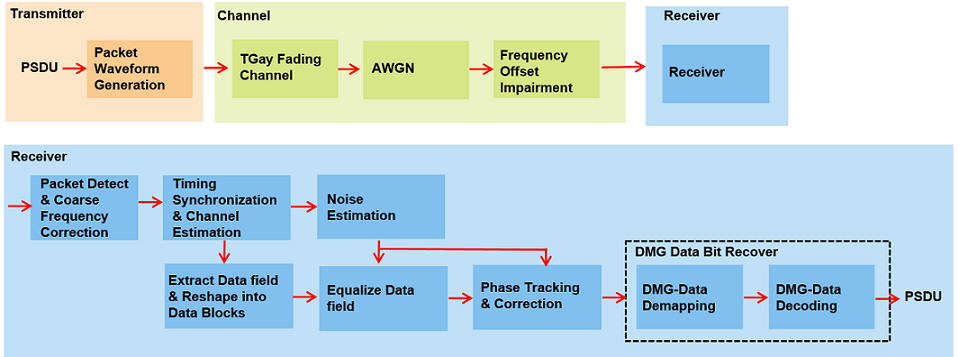

This example also demonstrates how a [parfor](docid:matlab_ref#f71-813245) loop can be used instead of the [for](docid:matlab_ref#buhafgy-1) loop when simulating each SNR point to speed up a simulation. [parfor](docid:matlab_ref#f71-813245), as part of the Parallel Computing Toolbox™, executes processing for each SNR in parallel to reduce the total simulation time.

## Waveform Configuration

An 802.11ad DMG SC PHY transmission is simulated in this example. The DMG format configuration object contains the format specific configuration of the transmission. The object is created using the [wlanDMGConfig](docid:wlan_ref#bvkqhra-1) function. The properties of the object contain the configuration of the transmitted packet. In this example the object is configured to generate a single carrier waveform of MCS "9". The MCS determines the PHY type used and in this example it must be a string within the range 1-12, or one of {9.1 12.1 12.2 12.3 12.4 12.5 12.6} to simulate the SC PHY.

% Create a format configuration object
cfgDMG = wlanDMGConfig;
mcs = "9"; % MCS specified as a string scalar or string vector
cfgDMG.PSDULength = 4096; % PSDULength in bytes

## Fading Channel Configuration

In this example we simulate a TGay channel model for the open area hotspot scenario, using the [wlanTGayChannel](docid:wlan_ref#mw_sysobj_wlanTGayChannel) object. Both the transmit and receive arrays are a 4x4 uniform rectangular array (URA). Ray-tracing is performed from the transmit to the receive array to derive two deterministic rays: one LOS ray and another NLOS ray with one-order reflection from the ground. Random rays and intra-cluster rays are subsequently generated according to the quasi-deterministic (Q-D) modeling approach and parameters in [ [2](about:blank<#14>) ]. Beamforming is performed to set the transmit and receive antenna steering direction along the ray with the maximum power. The fading channel impulse responses are normalized so no power gain or loss is introduced by the channel. Both the channel input and output signals are unpolarized.

% Get sampling rate and specify carrier frequency
fs = wlanSampleRate(cfgDMG);
fc = 60e9;     

% Create a TGay channel object
tgayChan = wlanTGayChannel;
tgayChan.SampleRate                = fs; 
tgayChan.CarrierFrequency          = fc;
tgayChan.Environment               = 'Open area hotspot';
tgayChan.TransmitArray.Size        = [4 4];
tgayChan.TransmitArrayPosition     = [0; 0; 6];     % Meters
tgayChan.TransmitArrayOrientation  = [0; 270; 0];   % Degrees
tgayChan.ReceiveArray.Size         = [4 4];
tgayChan.ReceiveArrayPosition      = [6; 6; 1.5];   % Meters 
tgayChan.ReceiveArrayOrientation   = [90; 0; 0];    % Degrees
tgayChan.BeamformingMethod         = 'Maximum power ray';
tgayChan.NormalizeImpulseResponses = true;
tgayChan.NormalizeChannelOutputs   = false;

Given the channel object configuration, we display a 3D map to show the environment and antenna array settings. The two deterministic rays from ray-tracing are also shown in the figure.

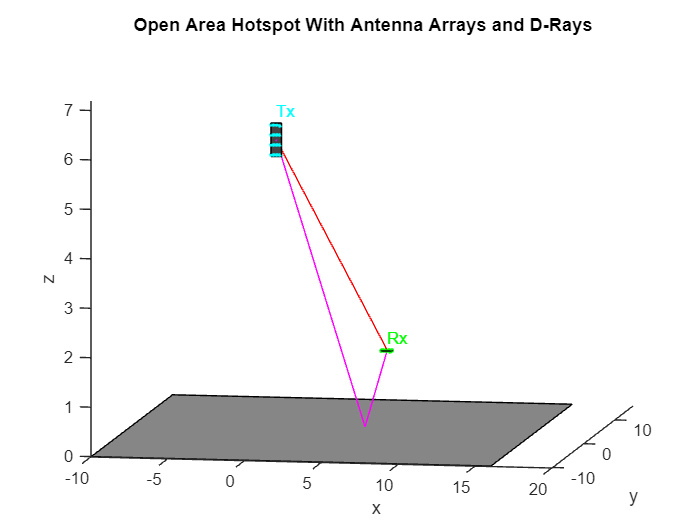

showEnvironment(tgayChan);

## Channel Impairment

The maximum tolerance for the transmitter center frequency must be within [-20, +20] ppm [ [1](about:blank<#13>) ]. In this example, a clock accuracy of 20ppm is considered to derive the CFO. The transmitted signal is delayed by 500 samples and also appended by 100 zero samples at the end to account for delays from TGay channel filtering.

ppm = 20;                 % Clock accuracy to drive the CFO (ppm)
freqOffset = ppm*1e-6*fc; % Carrier frequency offset (Hz)
delay = 500;              % Sample to delay the waveform
zeroPadding = 100;        % Add trailing zeros to allow for channel delay

## Simulation Parameters

For each SNR point (dB) in the cell `snrRanges` a number of packets are generated, passed through a channel and demodulated to determine the packet error rate. The SNR points to test are selected from `snrRanges` based on the MCS simulated.

snrRanges = {-2.5:0.5:0, ...      % MCS 1
             -0.5:0.75:3.5, ...   % MCS 2
              1.0:0.75:5, ...     % MCS 3
              1.5:0.75:5.5, ...   % MCS 4
              2.0:0.75:6.0, ...   % MCS 5
              2.5:0.75:6.5, ...   % MCS 6
              3:0.75:7, ...       % MCS 7
              4.5:0.75:8.5,...    % MCS 8
              6:0.5:8.5, ...      % MCS 9
              7.0:0.5:9.5, ...    % MCS 9.1
              8.5:1:13.5, ...     % MCS 10
              9.5:1.0:14.5, ...   % MCS 11
              10.5:1.25:17.0, ... % MCS 12
              11.5:1.5:19.0, ...  % MCS 12.1
              13.0:1.0:18, ...    % MCS 12.2
              14.0:1.0:19, ...    % MCS 12.3
              17.0:1.5:25, ...    % MCS 12.4
              19.0:2:29, ...      % MCS 12.5
              19.5:2:30};         % MCS 12.6

The number of packets tested at each SNR point is controlled by two parameters:

- `maxNumErrors` is the maximum number of packet errors simulated at each SNR point. When the number of packet errors reaches this limit, the simulation at this SNR point is complete.

- `maxNumPackets` is the maximum number of packets simulated at each SNR point and limits the length of the simulation if the packet error limit is not reached. 

The numbers chosen in this example will lead to a very short simulation. For meaningful results we recommend increasing the numbers.

maxNumErrors = 10;   % The maximum number of packet errors at an SNR point
maxNumPackets = 100; % The maximum number of packets at an SNR point

## Processing SNR Points

For each SNR point a number of packets are tested and the packet error rate calculated.

For each packet the following processing steps occur:

- A PSDU is created and encoded to create a single packet waveform.

- The waveform is passed through a TGay channel model. Different channel realizations are modeled for different packets.

- AWGN is added to the received waveform.

- The frequency offset impairment is added to each packet.

- The packet is detected.

- Carrier frequency offset is estimated and corrected.

- Fine timing synchronization is established. The CE field samples are provided for fine timing to allow for packet detection at the start of the STF. 

- The STF and CE fields are extracted from the synchronized received waveform. The noise and channel estimation is performed on the recovered fields respectively.

- The data field, excluding the first guard interval is extracted and reshaped into blocks. The received symbols in the data field are equalized.

- The received symbols are tracked and corrected for phase errors caused by any residual carrier frequency offset.

- The data field is decoded to recover the PSDU bits.

A [parfor](docid:matlab_ref#f71-813245) loop can be used to parallelize processing of the SNR points. To enable the use of parallel computing for increased speed comment out the [for](docid:matlab_ref#buhafgy-1) statement and uncomment the [parfor](docid:matlab_ref#f71-813245) statement below.

numSNR = numel(snrRanges{1}); % Number of SNR points
if ~isstring(mcs)
    error('MCS must be specified as a string scalar or string vector');
end
numMCS = numel(mcs);          % Number of MCS
packetErrorRate = zeros(numMCS,numSNR);
Ngi = 64; % Fixed GI length defined in the standard (20.6.3.2.5)
validMCS = string(sort([1:12 9.1 12.1:0.1:12.6]));

for imcs = 1:numMCS 
    cfgDMG.MCS = mcs(imcs);
    if ~strcmp(phyType(cfgDMG),'SC')
        error('This example only supports DMG SC PHY simulation');
    end
    ind = wlanFieldIndices(cfgDMG);
    snr = snrRanges{mcs(imcs)==validMCS}; % SNR points to simulate from MCS
    
    % parfor isnr = 1:numSNR % Use 'parfor' to speed up the simulation
    for isnr = 1:numSNR     % Use 'for' to debug the simulation
        % Set random substream index per iteration to ensure that each
        % iteration uses a repeatable set of random numbers
        stream = RandStream('combRecursive','Seed',1);
        stream.Substream = isnr;
        RandStream.setGlobalStream(stream);

        % Set simulation parameters
        numPacketErrors = 0;
        numPkt = 1; % Index of the transmitted packet
        
        while numPacketErrors<=maxNumErrors && numPkt<=maxNumPackets
            % Generate a packet waveform
            psdu = randi([0 1],cfgDMG.PSDULength*8,1);      
            txWaveform = wlanWaveformGenerator(psdu,cfgDMG);

            % Add delay and trailing zeros
            tx = [zeros(delay,1); txWaveform; zeros(zeroPadding,1)];

            % Transmit through a TGay channel. Reset the channel for a
            % different realization per packet. 
            reset(tgayChan);
            chanOut = tgayChan(tx);
            
            % Add noise
            rx = awgn(chanOut,snr(isnr));
            
            % Add CFO
            rx = frequencyOffset(rx,fs,freqOffset);

            % Packet detection
            threshold = 0.03; % Good for low SNRs
            pktStartOffset = dmgPacketDetect(rx,0,threshold);
            if isempty(pktStartOffset) % If empty no STF detected; packet error
                numPacketErrors = numPacketErrors+1;
                numPkt = numPkt+1;
                continue; % Go to next loop iteration
            end

            % Frequency offset estimation and correction
            stf = rx(pktStartOffset+(ind.DMGSTF(1):ind.DMGSTF(2)));
            fOffsetEst = dmgCFOEstimate(stf);
            rx = frequencyOffset(rx,fs,-fOffsetEst);

            % Symbol timing and channel estimate
            preamblefield = rx(pktStartOffset+1:pktStartOffset+ind.DMGHeader(2),:);
            [symbolTimingOffset,chanEst] = dmgTimingAndChannelEstimate(preamblefield);
            startOffset = pktStartOffset+symbolTimingOffset;

            % If not enough samples to decode detected data field start,
            % then assume synchronization error and packet error
            if (startOffset+ind.DMGData(2))>size(rx,1)
                numPacketErrors = numPacketErrors+1;
                numPkt = numPkt+1;
                continue; % Go to next loop iteration
            end

            % Noise estimation using the STF as repeating sequence
            stf = rx(pktStartOffset+(ind.DMGSTF(1):ind.DMGSTF(2)));
            nVarEst = dmgSTFNoiseEstimate(stf);

            % Extract data field (ignore first GI)
            rxData = rx(startOffset+((ind.DMGData(1)+Ngi):ind.DMGData(2)));

            % Linear frequency domain equalization
            rxEqDataBlks = dmgSingleCarrierFDE(rxData,chanEst,nVarEst);

            % Unique word phase tracking
            rxEqDataBlks = dmgUniqueWordPhaseTracking(rxEqDataBlks);

            % Discard GI from all blocks
            rxDataSym = rxEqDataBlks(1:end-Ngi,:); 

            % Recover the transmitted PSDU from DMG Data field
            dataDecode = wlanDMGDataBitRecover(rxDataSym,nVarEst,cfgDMG);

            % Determine if any bits are in error, i.e. a packet error
            packetError = any(biterr(psdu,dataDecode));
            numPacketErrors = numPacketErrors+packetError;
            numPkt = numPkt+1;
        end
        
        % Calculate packet error rate (PER) at SNR point
        packetErrorRate(imcs,isnr) = numPacketErrors/(numPkt-1);
        disp(join(["     MCS:" cfgDMG.MCS ", SNR " ...
            num2str(snr(isnr)) " completed after " ...
            num2str(numPkt-1) " packets, PER: " ... 
            num2str(packetErrorRate(imcs,isnr))],""));
    end
end

     MCS:9, SNR 6 completed after 11 packets, PER: 1
     MCS:9, SNR 6.5 completed after 16 packets, PER: 0.6875
     MCS:9, SNR 7 completed after 38 packets, PER: 0.28947
     MCS:9, SNR 7.5 completed after 99 packets, PER: 0.11111
     MCS:9, SNR 8 completed after 100 packets, PER: 0.04
     MCS:9, SNR 8.5 completed after 100 packets, PER: 0.01


## Plot Packet Error Rate vs SNR Results

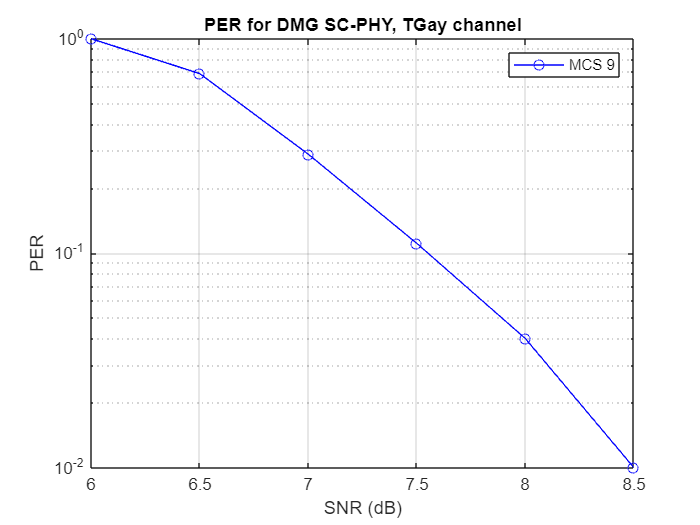

markers = 'ox*sd^v><ph+ox*sd^v';
color = 'bmcrgbrkymcrgbrkymc';
figure;
for imcs = 1:numMCS
    semilogy(snrRanges{mcs(imcs)==validMCS},packetErrorRate(imcs,:).',['-' markers(imcs) color(imcs)]);
    hold on;
end
grid on;
xlabel('SNR (dB)');
ylabel('PER');
dataStr = arrayfun(@(x)sprintf('MCS %s',x),mcs,'UniformOutput',false);
legend(dataStr);
title('PER for DMG SC-PHY, TGay channel');

## Further Exploration

The number of packets tested at each SNR point is controlled by two parameters; `maxNumErrors` and `maxNumPackets`. For meaningful results, it is recommended that these values should be larger than those presented in this example. Increasing the number of packets simulated allows the PER under different scenarios to be compared. Try changing the MCS value and compare the packet error rate. As an example, the figure below was created by running the example for all single carrier MCS with  `PSDULength`: 8192 bytes, `maxNumErrors`: 1000 and `maxNumPackets`: 10000.

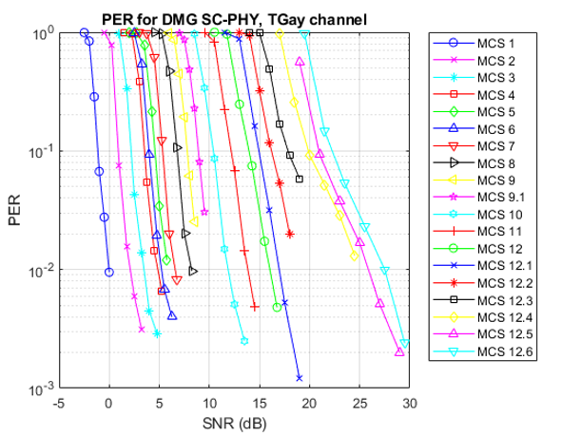

Explore the TGay channel settings by changing the environment ('Street canyon hotspot' or 'Large hotel lobby'), user configurations, polarization type, array configurations, beamforming method and so on. In the street canyon scenario, the object calculates deterministic rays up to 1-order reflection from the ground and walls. In the hotel lobby scenario, the deterministic rays are up to 2-order reflection from the ground, ceiling and/or walls. Due to the additional reflection of rays, the PER results are typically better than the above obtained from the open area scenario.

## Selected Bibliography

- IEEE Std 802.11™-2020. IEEE Standard for Information Technology - Telecommunications and Information Exchange between Systems - Local and Metropolitan Area Networks - Specific Requirements - Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications.

- A. Maltsev and et. al, Channel Models for IEEE 802.11ay, IEEE 802.11-15/1150r9, Mar. 2017.

*Copyright 2017-2022 The MathWorks, Inc.*